# Record your voice

Record the sentence: "Hello ... is it me your looking for ?" using 48000 sample rate. Please try to enunciate clearly as if you are a BBC announcer. We will use this sentence in further work.

% you should use the code below to record audio
recTime = 6.0 ; % seconds
devId = 3 ; % microphone
%device
fs = 48000 ; % I like to use 48 kHz
bufSiz = 2048 ; 
userStart = true ; % Have to press return to start recording

recSig = RecordAudio(recTime, devId, fs, bufSiz, userStart) ;

Press a key to start recording


You can then select a restricted portion of the signal which removes the rubbish at the start and end of the signal, plot the signal first:

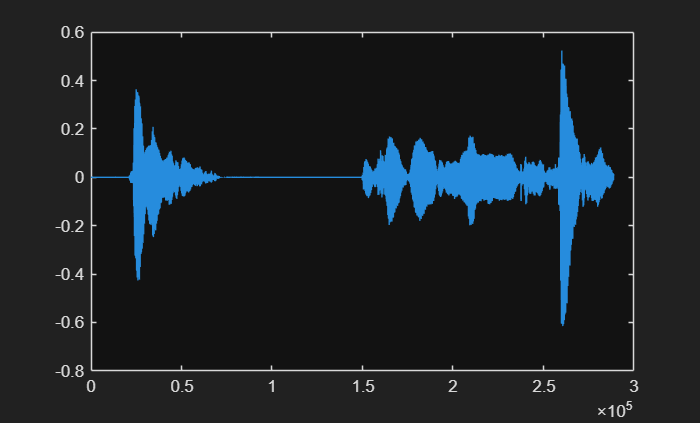

% Plot signal
figure ;
plot(recSig) % x-axis is the sample number
set(gcf,'Visible','On')

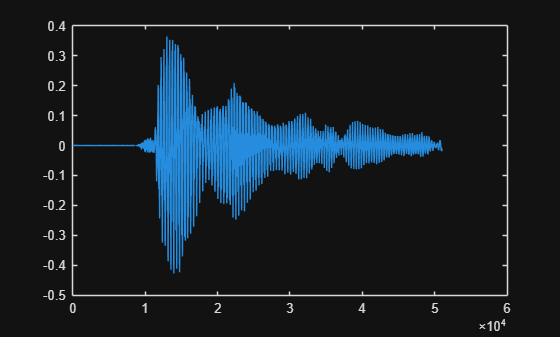

recSigWin = recSig(12000:63000) ;
% plot the windowed signal
figure ;
plot(recSigWin)

## Truncated Ideal Low-Pass Filter

Create an ideal truncated low-pass filter based on the following formula


$$H(e^{j\,\omega}) = \left\{\begin{array}{ll}
1\cdot e^{-j\,\alpha\,\omega}\text{,} & |\omega| \lt \omega_c \\
0\text{,} & \omega_c < |\omega| \le \pi
\end{array}$$


## Compute the Analytic Solution for the impulse response below:

Show your work using latex equations below.

Put work here:


$$h(n) = \frac{1}{2\,\pi}\int_{-\omega_c}^{\omega_c}e^{-j\,\alpha\,\omega}e^{j\,n\,\omega}d\omega = \frac{1}{2\,\pi}\frac{e^{j\,(n-\alpha)\,\omega}}{j\,(n-\alpha)}|_{-\omega_c}^{\omega_c} = \frac{\sin\left[\omega_c\,(n-\alpha)\right]}{\pi\,(n-\alpha)$$


Determine and plot the truncated impulse response 


$$h[n] \ \text{for} \ 0 \le n < N-1$$


using N = 61, $\alpha = 30$. Choose $\omega_c$ so that the cut-off frequency is 1500 Hz.

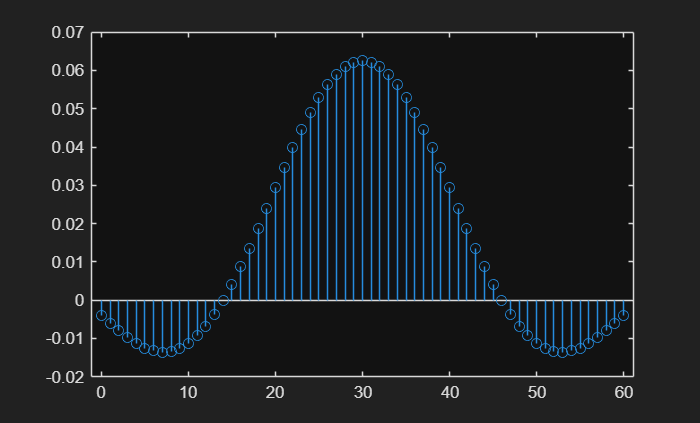

% Put your code here
n = 0:60;                    % N = 61 points, 0 to N-1
alpha = 30;                  % delay (centre of filter)
fs = 48000;                  % what you used to record the audio
wc = 2 * pi * 1500 / fs;     % normalised cutoff for 1500 Hz

% Matlab sinc is sin(pi x)/(pi x)
% so sin(wc*(n-alpha))/(pi*(n-alpha)) = (wc/pi) * sinc(wc*(n-alpha)/pi)
lpFilt = (wc/pi) * sinc(wc*(n-alpha)/pi);

figure;
set(gcf,'Visible','On')
stem(n, lpFilt)